# 5th order QUintic Trajectories

% Intial Conditions (Point A)
ta = 1; qa = -30; va = 0; ac_a = 0;

% Via point (point C)
tc = 5; qc = 10; vc = 2; ac_c = 0.4;

% Final Conditions (Point B)
tb = 10; qb = 90; vb = 0; ac_b = 0;

% Compute A to C  trajectory
[t_ac, qt_ac, vt_ac, at_ac] = quintic(ta, tc, qa, qc, va, vc, ac_a, ac_c);

K =   -30.0000
         0
         0
   10.0000
    2.0000
    0.4000


T =            1           1           1           1           1           1
           0           1           2           3           4           5
           0           0           2           6          12          20
           1           5          25         125         625        3125
           0           1          10          75         500        3125
           0           0           2          30         300        2500


A =   -38.1641
   27.0703
  -32.4406
   16.5406
   -3.2203
    0.2141


% Compute C to B  trajectory
[t_cb, qt_cb, vt_cb, at_cb] = quintic(tc, tb, qc, qb, vc, vb, ac_c, ac_b);

K =    10.0000
    2.0000
    0.4000
   90.0000
         0
         0


T =            1           5          25         125         625        3125
           0           1          10          75         500        3125
           0           0           2          30         300        2500
           1          10         100        1000       10000      100000
           0           1          20         300        4000       50000
           0           0           2          60        1200       20000


A = 	1.0e+03 *

   -2.2700
    1.7640
   -0.5300
    0.0768
   -0.0053
    0.0001


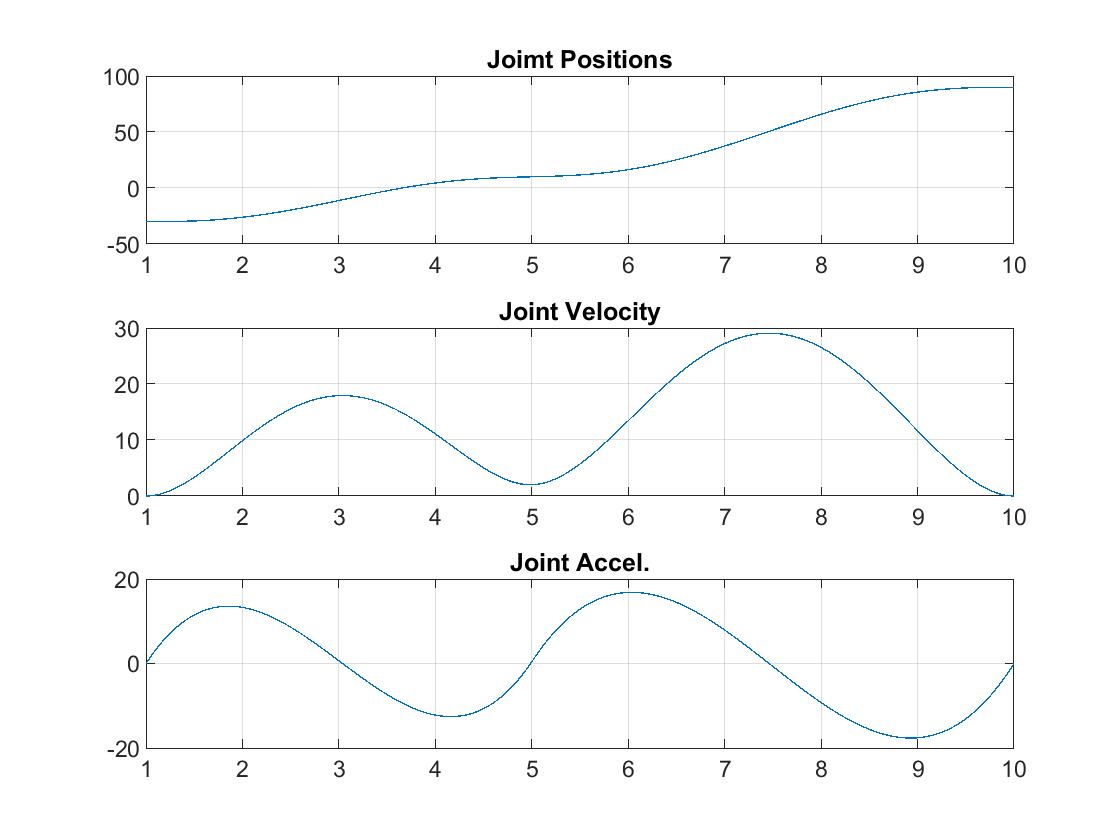


% Merging trajectories A --> C --> B
t = [t_ac t_cb];
qt = [qt_ac qt_cb];
vt = [vt_ac vt_cb];
at = [at_ac at_cb];

figure;
subplot(3,1,1), plot(t, qt), ...
    title('Joimt Positions'), grid
subplot(3,1,2),plot(t, vt), ...
    title('Joint Velocity'), grid
subplot(3,1,3),plot(t, at), ...
    title('Joint Accel.'), grid

function [t, qt, vt, at] = quintic(ti, tf, qi, qf, vi, vf, aci, acf)
    
    K = [qi vi aci qf vf acf]'

    T = [1 ti ti^2 ti^3   ti^4     ti^5;
         0 1  2*ti 3*ti^2 4*ti^3   5*ti^4;
         0 0  2    6*ti   12*ti^2  20*ti^3;
         1 tf tf^2 tf^3   tf^4     tf^5;
         0 1  2*tf 3*tf^2 4*tf^3   5*tf^4;
         0 0  2    6*tf   12*tf^2  20*tf^3]
    
A = inv(T) * K
    
    a0 = A(1); a1 = A(2);
    a2 = A(3); a3 = A(4);
    a4 = A(5); a5 = A(6);
    
    t = linspace(ti, tf, 100); % time scale

    qt = a0 + a1*t + a2*t.^2 + a3*t.^3 + a4*t.^4 + a5*t.^5;        % joint positions
    vt = 0  + a1   + 2*a2*t  + 3*a3*t.^2 + 4*a4*t.^3 + 5*a5*t.^4;  % joint velocities
    at = 0  +  0   + 2*a2    + 6*a3*t  + 12*a4*t.^2 + 20*a5*t.^3;     % joint acceleration

end
